% COV in MATLAB
a = randn(1, 80);
cov(a) % return the var of a

ans = 0.7980

var(a)

ans = 0.7980


b = randn(1, 80);
cov(a, b)

ans =     0.7980    0.1399
    0.1399    0.8136


% S(a)      COV(a, b)
% COV(a ,b) S(b)

f = randn(30, 4);
cov(f)

ans =     1.0908    0.1736   -0.5498   -0.1798
    0.1736    1.0575    0.1852    0.1066
   -0.5498    0.1852    1.1031   -0.0194
   -0.1798    0.1066   -0.0194    1.0031


% f is a MxN metrix
% return a NxN metrix
% diag(cov(f)) is var of each row
% cov(f)(i, j) is COV(f(:, i), f(:, j))

A = randn(10);
B = randn(10);
cov(A, B)

ans =     1.2470    0.0322
    0.0322    1.1358


% S(A(:))         COV(A(:), B(:))
% COV(B(:), A(:)) S(B(:))

% corrcoef
A = randn(6, 1);
B = randn(6, 1);
C = [A, B, 2*B+3];
corrcoef(C)

ans =     1.0000    0.4733    0.4733
    0.4733    1.0000    1.0000
    0.4733    1.0000    1.0000



corrcoef(A, B)

ans =     1.0000    0.4733
    0.4733    1.0000




D = randn(30, 3);
D(:, 4) = sum(D, 2);
[R, P] = corrcoef(D);
R

R =     1.0000    0.0702   -0.1076    0.5392
    0.0702    1.0000   -0.0455    0.6686
   -0.1076   -0.0455    1.0000    0.4706
    0.5392    0.6686    0.4706    1.0000


P % P-Values

P =     1.0000    0.7123    0.5715    0.0021
    0.7123    1.0000    0.8112    0.0001
    0.5715    0.8112    1.0000    0.0087
    0.0021    0.0001    0.0087    1.0000


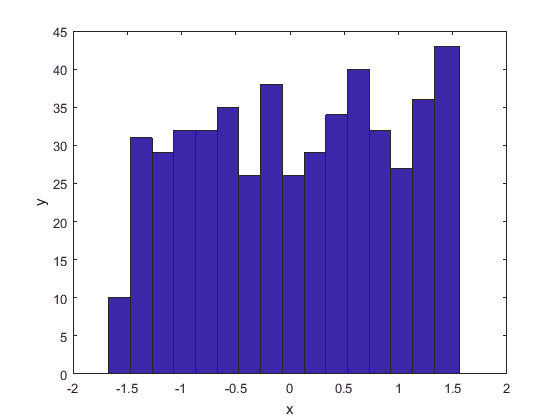

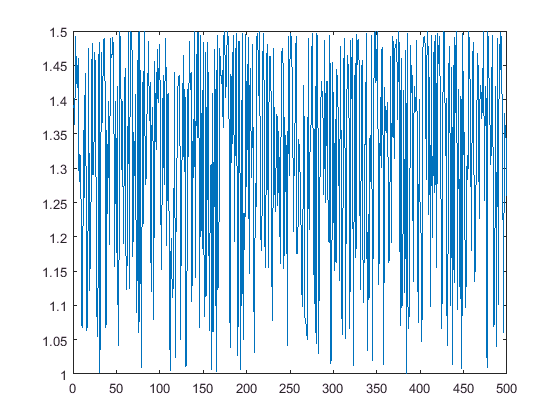

n = 500;
x = zeros(1, n);
k = 0;

while k<n
   a = rand *pi - pi/2;
   b = rand/2;
   if b<(cos(a)/2+1)
      k = k+1;
      x(k) = a;
   end
end

hist(x, -pi/2:0.2:pi/2);
xlabel('x');
ylabel('y');